# 円筒動画作成

## Path

環境に応じて変更

% ディレクトリ
% dir = '/Users/daiki_daiku/Library/CloudStorage/Box-Box/Personal/study/Data/2023/231112_甲賀出張実験/計測データ';
% videodir = '/Users/daiki_daiku/Library/CloudStorage/Box-Box/Personal/study/Data/2023/231112_甲賀出張実験/動画';
dir =fullfile("C:\Users\daiki\Box\Personal\study\Data\2023\231112_甲賀出張実験\計測データ");
videodir =fullfile("C:\Users\daiki\Box\Personal\study\Data\2023\231112_甲賀出張実験\計測データ");
% データファイル名
file_name = '11.csv';
% ゲージファイル名
gagefile_name = 'gage.xlsx';
% 書き出しビデオ名
video_name = append(string(datetime),'.mp4');

## データ読込

基本変更しない

data_dir = fullfile(dir,file_name);
% gage_dir = fullfile(dir,gagefile_name);
video_dir = fullfile(videodir,video_name);
% データ
data1 = readmatrix([data_dir]);
% gage
% gage = readmatrix([gage_dir]);

## 変数

視点・終点 :  gageファイルの3列目に始点と終点の列数を記入

% 始点
% gage1 = gage(1, 3);
gage1 = 5996;
% 終点
% gage2 = gage(15, 3);
gage2 = 7795;
% 巻きの高さ
H = 70;
% 直径
D = 40;
% 周波数
f = 50;
% 倍速再生
frameRate = 2;
% 巻き数
% m = 19;
l =(7795-5996)*2.6;
pir = pi *D;
m = l/pir;

## データ整理

基本変更しない

% データ数
n = gage2 - gage1 + 1;
% データ
Z = data1(6:end, gage1:gage2) * (-1);
% データサイズ
sz = size(Z);
row = sz(1);
% プロット位置
theta = linspace(0, 2 * m * pi, n);
x = D/2 * cos(theta);
y = D/2 * sin(theta);
h = linspace(H, 0, n);
t = linspace(0, (row - 0.01) / f, row);
% colorbar用
zmax = max(max(Z));
zmin = min(min(Z));
% zmean = mean(Z);
% zstd=rms(Z);
% zmin=zmean-2 * zstd;
% zmax=zmean+2 * zstd;

## 動画セクション

基本変更しない

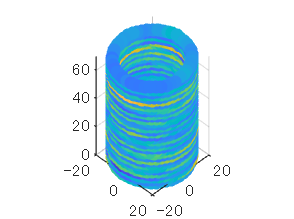

ファイルが見つかりません。ファイルが存在し、パスが有効であることを確認してください。

for D = 40:5:80
    x = D/2 * cos(theta);
    y = D/2 * sin(theta);
    % T = 0.01:1/f:row / f;
    % for i = 1:length(T)
    %     z{i} = Z(i,:);
    % end
    fig = figure; % Figure オブジェクトの生成
    xlim([-1.5 1.5]);
    ylim([-1.5 1.5]);
    zlim([0 75]);
    frames(row) = struct('cdata', [], 'colormap', []); % 各フレームの画像データを格納する配列
    H=scatter3(x, y, h, [], z{1}, 'filled');
    view(45, 45)
    daspect([1 1 1])
    for i = 1:row
        set(H, 'CData', z{i});
        clim([zmin zmax]);
        drawnow;
        frames(i) = getframe(fig);
    end
    video_name = append(string(datetime),'.mp4');
    video_dir2 = fullfile(video_dir,append(int2str(D),video_name));
    video = VideoWriter(video_dir2, 'MPEG-4');
    video.FrameRate = f*frameRate;
    open(video);
    writeVideo(video, frames);
    close(video);
end